## File formats and loading data in MATLAB

#### Uncompressed vs. compressed data

In general, data can be in an uncompressed file format or a compressed file format. 

Uncompressed file formats (csv, txt) are typically simple, usually just one big table of data with some column and rows named. To read in such a file format one would need to know the delimeter (what separates data values from one another), how many rows and columns are labels, and how missing data is labelled (often a very large negative or positive value that is not physically achievable by the quantity in question). The downside of uncompressed file formats is that for large datasets they take up lots of space and can be cumbersome to load and typically hard to load subsets of the data.

Compressed file formats are useful for very large datasets and datasets where you might only want to load some data at a time (therefore making it easier to load large datasets into memory). Common compressed file formats in Earth Science are netcdf, mat (for MATLAB, but can be loaded in python as well), npz (for Python), pkl (also for Python). Other software may use proprietary file formats to save data. Compressed data cannot just be easily opened and scanned visually (like a txt file), and typically requires a bit more of a learning curve. 

#### Loading data in MATLAB

MATLAB generally makes pulling data into a matrix quite easy from a variety of file formats. For simple tasks with small datasets MATLAB can often be the easiest way to do some basic analyses. Python is much more powerful, and as we will learn throughout the semester, most modern analysis tools (statistics/ML, etc.) are being built for Python, but MATLAB is still an easy-to-use platform for data analysis.

The MATLAB proprietary data format is .mat. It is very easy to load .mat data in MATLAB.

load('ATL_SEA_monthlytemps.mat')

You can also just load some variables from the file

load('ATL_SEA_monthlytemps.mat','ATLtemp')

#### "Import Data" Tool

For other data types (mainly uncompressed), the "Import Data" GUI tool (see your MATLAB menu bar above) makes importing data from an unfamiliar file super easy. It automatically detects things like delimiters and headers, and also gives you the option of importing only part of the data using highlighting of cells. It can also important into a variety of different MATLAB data types, including a "table" which allows mixing of strings and numbers. However, most data analysis functions requires data to be a "Numeric Matrix".

**Use the data import tool to import the ATL_MonMeanTemp_1879_2020.csv file**

Also note based on your selections, you can generate a script which imports the data if you want to use this to make an automated script for importing many similar data files.

#### NetCDF File Format

Perhaps the most widely used file format in Earth Sciences (particularly climate/ocean/atmosphere) for the last 30 years is NetCDF. It is a highly compressed file format that is useful for displaying spatiotemporal data for many variables. Large observational data and output from complex models (e.g. climate models) is typically distributed by detault as NetCDF. Recently, other modern compressed file formats (e.g., Zarr, Parquet) have become popular (specifically in Python), particular because they make it even easier to load in small chunks of datasets, which is especially good for very large datasets (100+ GB) and doing things in the cloud. However, you are still the most likely to encounter NetCDF files, so we will focus on them here. We start by displaying all the information about the netcdf file, its dimensions, attributes and variables.

What follows is based on [Chad Greene's netCDF tutorial for MATLAB](https://www.chadagreene.com/CDT/tutorial_netcdf.html). If you end up using MATLAB a lot for manipulating and analyzing data from netCDF files, I highly recommend you to download his [free add-on Climate Data Toolbox for MATLAB](https://www.chadagreene.com/CDT/CDT_Contents.html).

ncdisp 'ERA5_2mtemp_SLP_2022.nc'

Source:
           /Users/arobel3/Dropbox (GaTech)/Teaching/PracticalMathCoding/Lectures/ERA5_2mtemp_SLP_2022.nc
Format:
           64bit
Global Attributes:
           Conventions = 'CF-1.6'
           history     = '2023-08-16 15:10:53 GMT by grib_to_netcdf-2.25.1: /opt/ecmwf/mars-client/bin/grib_to_netcdf.bin -S param -o /cache/data8/adaptor.mars.internal-1692198652.656473-26287-5-95c07332-7acf-4015-8b62-ec3d404afcd6.nc /cache/tmp/95c07332-7acf-4015-8b62-ec3d404afcd6-adaptor.mars.internal-1692198650.4936817-26287-8-tmp.grib'
Dimensions:
           longitude = 1440
           latitude  = 721
           time      = 6
Variables:
    longitude
           Size:       1440x1
           Dimensions: longitude
           Datatype:   single
           Attributes:
                       units     = 'degrees_east'
                       long_name = 'longitude'
    latitude 
           Size:       721x1
           Dimensions: latitude
           Datatype:   single
           Attributes:
         

To read in data we use ncread with the file name, and specifying which variable we want to load.

lat = ncread('ERA5_2mtemp_SLP_2022.nc','latitude');
lon = ncread('ERA5_2mtemp_SLP_2022.nc','longitude');
T = ncread('ERA5_2mtemp_SLP_2022.nc','t2m');
time = ncread('ERA5_2mtemp_SLP_2022.nc','time');

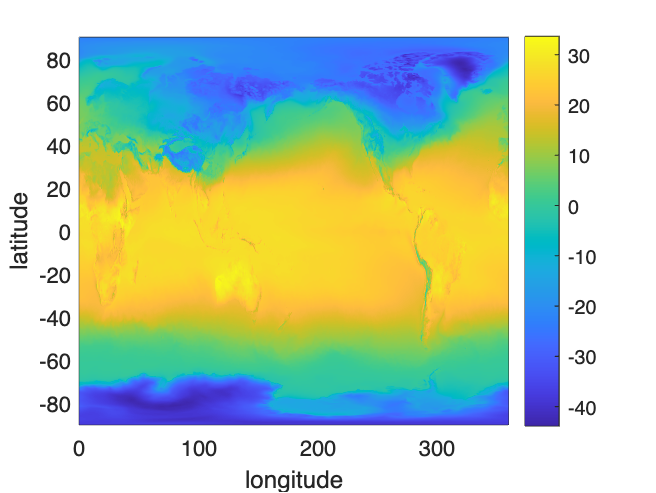

[Lon,Lat] = meshgrid(lon,lat);
pcolor(double(Lon),double(Lat),squeeze(T(:,:,2))'-273.15)
shading interp % eliminates black lines between grid cells
xlabel longitude
ylabel latitude
colorbar

The time variable can be converted to datetime format using special functions (need to download from MATLAB central) like ncdateread.

MATLAB's conventional netCDF reading capabilities can read part of a variable, but only in contiguous chunks. We also need to know the indices over which we want to read. Here is an example of how to find the indices for the Southeastern US.

% Find lat/lon around SE US (note longitude in 0-360 format)
ind1 = find(lon>=250 & lon<=280);
ind2 = find(lat>=25 & lat<=40);

% Clip lat and lon to their specified range:
latm = lat(ind2);
lonm = lon(ind1);

% Make a grid:
[LatM,LonM] = meshgrid(latm,lonm);

start = [ind1(1) ind2(1) 2];
stride = [length(ind1) length(ind2) 1];

% Load Feb surface pressure and temp for SE:
sp = ncread('ERA5_2mtemp_SLP_2022.nc','sp',start,stride);
Tm = ncread('ERA5_2mtemp_SLP_2022.nc','t2m',start,stride);

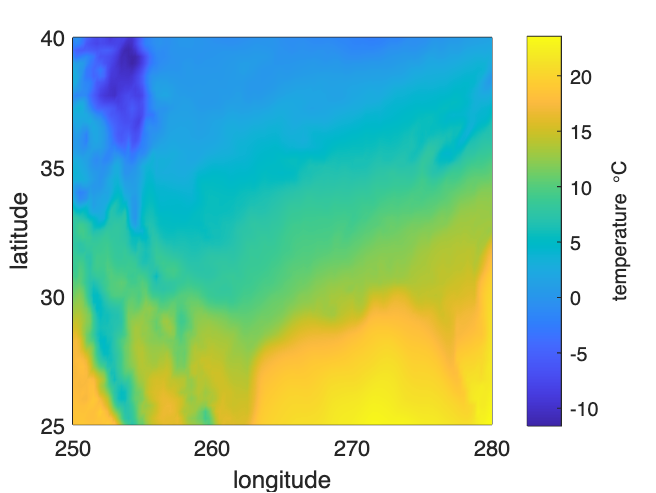

figure
pcolor(LonM,LatM,Tm-273.15) % temperature in deg C
shading interp
%caxis([17 44]) % color axis limits
cb = colorbar;
ylabel(cb,'temperature \circC')
hold on
xlabel 'longitude'
ylabel 'latitude'